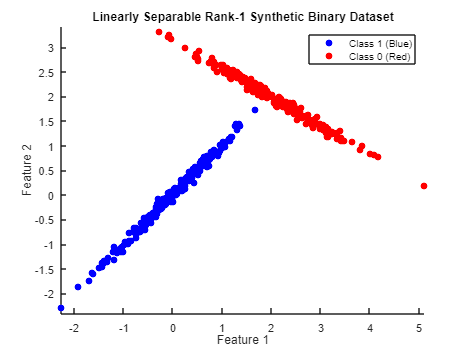

% Parameters
num_points = 500; % Total number of points
class1_angle = pi/4; % Principal direction for class 1 (45 degrees)
class2_angle = -pi/6; % Principal direction for class 0 (-30 degrees)
noise_level = 0.05; % Small noise to spread points around the principal line
class_distance = 2; % Distance between the classes to ensure separability

% Generate class 1 points
class1_t = randn(num_points/2, 1); % Parameter along the principal component
class1_x = class1_t * cos(class1_angle) + randn(num_points/2, 1) * noise_level; % Feature 1
class1_y = class1_t * sin(class1_angle) + randn(num_points/2, 1) * noise_level; % Feature 2
class1_labels = ones(num_points/2, 1); % Label = 1

% Generate class 0 points
class2_t = randn(num_points/2, 1); % Parameter along the principal component
class2_x = class2_t * cos(class2_angle) + randn(num_points/2, 1) * noise_level + class_distance; % Feature 1
class2_y = class2_t * sin(class2_angle) + randn(num_points/2, 1) * noise_level + class_distance; % Feature 2
class2_labels = zeros(num_points/2, 1); % Label = 0

% Combine the dataset
X = [class1_x, class1_y; class2_x, class2_y]; % Features
Y = [class1_labels; class2_labels]; % Labels

% Scatter plot of the dataset
figure;
scatter(class1_x, class1_y, 'b', 'filled'); hold on;
scatter(class2_x, class2_y, 'r', 'filled');
title('Linearly Separable Rank-1 Synthetic Binary Dataset');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Class 1 (Blue)', 'Class 0 (Red)');
axis equal;


% Save to CSV if needed
dataset = [X, Y]

dataset =    -1.9239   -1.8569    1.0000
   -0.9982   -1.1508    1.0000
   -0.0379   -0.1144    1.0000
   -1.6426   -1.5683    1.0000
    0.2655    0.1900    1.0000
   -0.3290   -0.2429    1.0000
    0.0434    0.1469    1.0000
   -1.6960   -1.7289    1.0000
   -0.4190   -0.4535    1.0000
    0.3393    0.3072    1.0000


csvwrite('toy_dataset.csv', dataset);

disp('Linearly separable dataset created and saved as linearly_separable_rank1_dataset.csv');

Linearly separable dataset created and saved as linearly_separable_rank1_dataset.csv
